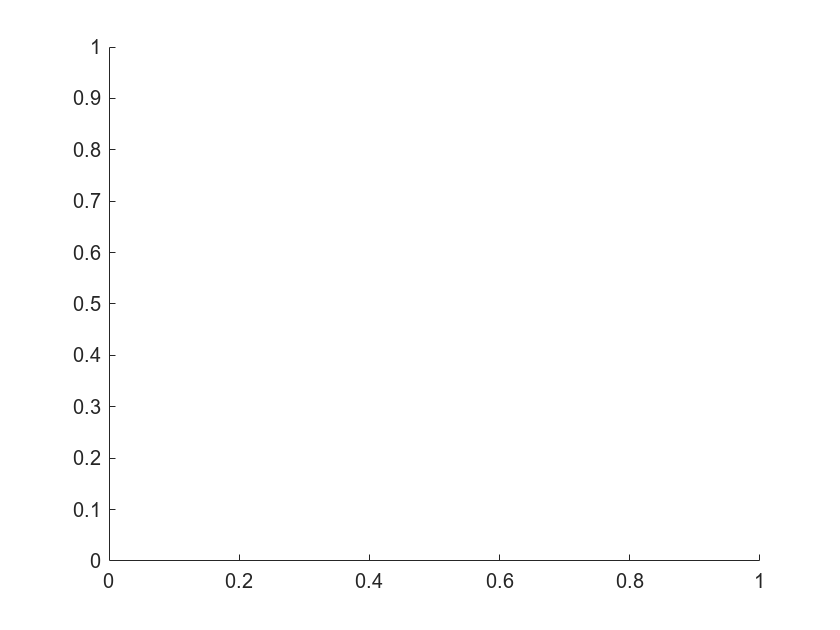

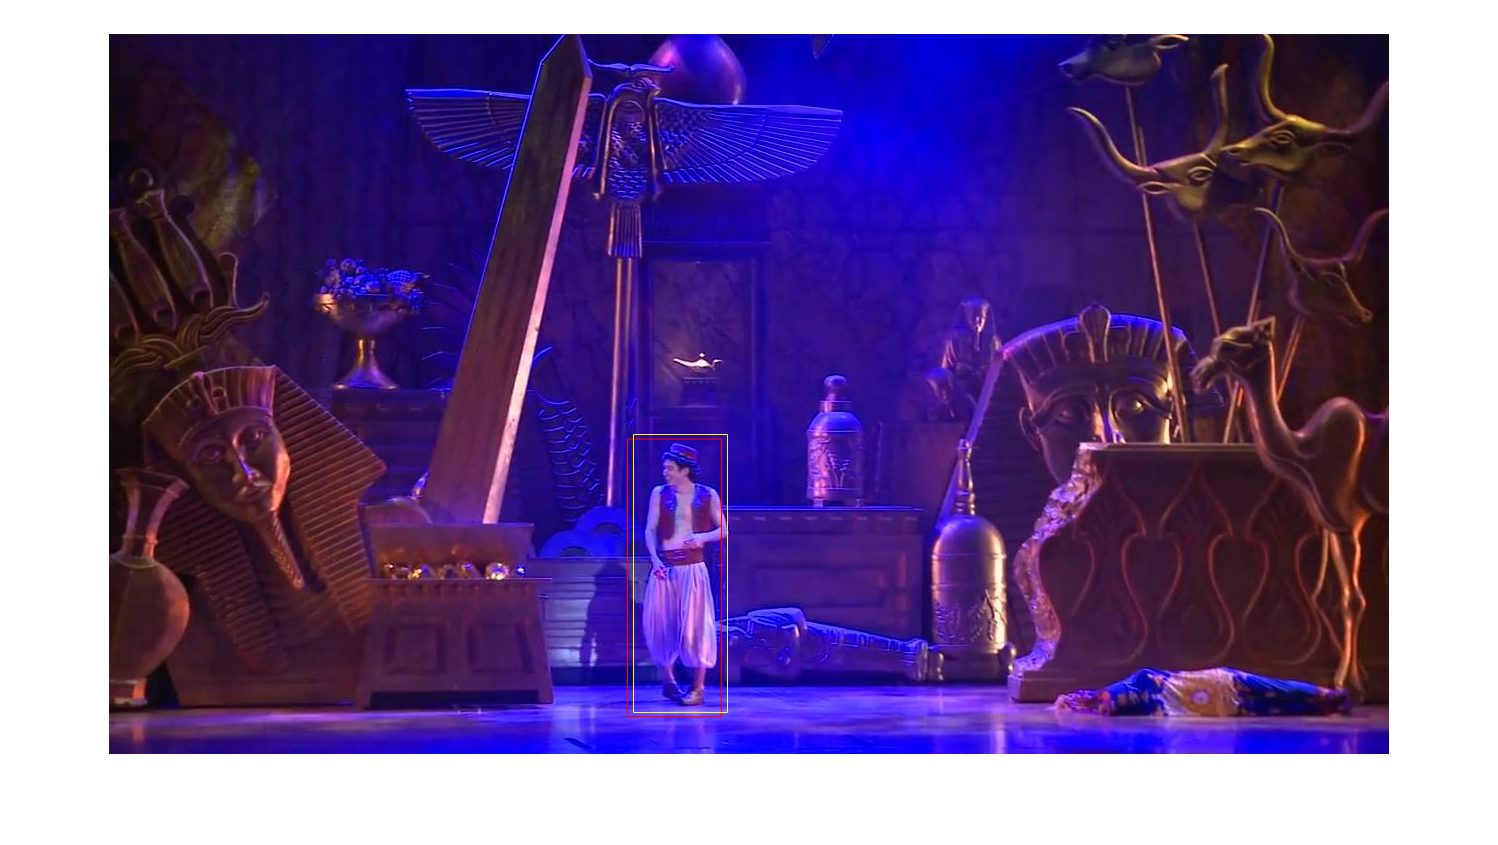

videoNames =dir("TinyTLP\");
%videoNames = {'Alladin','PolarBear1'};
nFrames = 100;
%OverlappingRates = zeros([size(videoNames,2), nFrames]);
OverlappingRates = zeros([50, nFrames]);
%size(videoNames,1)
for i=3:3
    name = videoNames(i).name;
    %name = videoNames{i};
    OverlappingRates(i-2,:) = strategy(name,nFrames);
end


%%

function ORatio = strategy(videoName, nFrames)
    close all
    hold off

    path1 = strcat('./TinyTLP/', videoName);
    path11 = strcat(path1,'/groundtruth_rect.txt');
    path2 = strcat(path1,'/img/*.jpg');

    BB = importdata(path11);
    Idir = dir(path2);

    figure
    hold on

    previousBB = BB(1,2:5);
    filename = horzcat(Idir(1).folder,'/',Idir(1).name);
    I = imread(filename);
    previousCrop = imcrop(I,previousBB);

    ORatio = zeros(1,nFrames);

    for i=1:nFrames
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        I = imread(filename);


        bestBB = previousBB;
        bestCrop = imcrop(I, bestBB);
        min_diff = computeDiff(previousCrop,bestCrop);
        i_step = floor(BB(i,4)/25);
        j_step = floor(BB(i,5)/25);
        for i_cord = 1:i_step:previousBB(3)
            for j_cord = 1:j_step:previousBB(4)
                [tlx,tly] = topLeftCoordinate([previousBB(1)+i_cord,previousBB(2)+j_cord],previousBB(3),previousBB(4));
                possibleBB = [tlx,tly,previousBB(3),previousBB(4)];
                Crop = imcrop(I, possibleBB);
                diff = computeDiff(previousCrop,Crop);
                if diff < min_diff
                    min_diff = diff;
                    bestBB = possibleBB;
                end
            end
        end
        % Càlcul de Bounding Box i tractament de resultat
        ORatio(1,i) = bboxOverlapRatio([bestBB(1),bestBB(2),BB(i,4),BB(i,5)],BB(i,2:5));
       
        imshow(I)
        rectangle('Position',[bestBB(1),bestBB(2),BB(i,4),BB(i,5)],'EdgeColor','red');
        rectangle('Position',BB(i,2:5),'EdgeColor','yellow');
        drawnow

        % Actualitzar previous...
        previousBB = bestBB;
    end
end

function diff = computeDiff(I1,I2)
    if size(I1) == size(I2)
        hist1 = calculateHistogram(I1);
        hist2 = calculateHistogram(I2);
        diff = compareHistograms(hist1,hist2);
    else
        diff = 10000000000;
    end
end

function [minx, miny] = topLeftCoordinate(centralPoint, width, height)
    minx = centralPoint(1) - width/2;
    miny = centralPoint(2) - height/2; 
end
%% 
% Comentari: Hue no funciona, hem provat el video Hideway amb el kalman original 
% però canviant el rgb2gray a rgb2hsv ( i agafant la component hue). No funciona 
% ja que es perd molta informació de l'imatge: (comparar captura original, gray 
% i hsv).
function [hist] = calculateHistogram(im)
    I = sum(rgb2gray(im),'all')/(size(im,1)*size(im,2))/255;
    im_norm = (double(im)/255)/(3*I);
    hist = zeros([16,16]);
    for i = 1:size(im, 1)
        for j = 1:size(im, 2)
            r = min(floor(15*im_norm(i,j,1)) + 1, 16);
            g = min(floor(15*im_norm(i,j,2)) + 1, 16);
            hist(r,g) = hist(r,g) + 1;
        end
    end
end

function [s] = compareHistograms(hist1, hist2)
    s = 0;
    for i = 1:16
        for j = 1:16
            if (hist1(i,j) + hist2(i,j) > 0)
                s = s + (hist1(i,j) - hist2(i,j))*(hist1(i,j) - hist2(i,j))/(hist1(i,j) + hist2(i,j));
            end
        end
    end
end